# PM2.5 Modeling- Chattogram

## Setup the Import Options and import the data

Generated using import tool. The data is saved in excel format. 

opts = spreadsheetImportOptions("NumVariables", 18);

% Specify sheet and range
opts.Sheet = "CAMS7";
opts.DataRange = "A2:R1703";

% Specify column names and types
opts.VariableNames = ["Year", "Month", "Day", "MaximumTemperatureC", "MinimumTemperatureC", "COppm", "SO2ppb", "NO2ppb", "O3ppb", "WindSpeedknots", "WindDirection", "RelativeHumidity", "DryBulbTemperatureC", "SolarRadiationWm2", "Rainfallmm", "SunshineHourshours","PM10gm3", "PM25gm3"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Specify variable properties
opts = setvaropts(opts, "WindDirection", "EmptyFieldRule", "auto");

% Import the data
CAMSraw = readtable("F:\OneDrive - BUET\Papers\PM2.5 modelling\Model\Code\CAMS.xlsx", opts, "UseExcel", false);
clear opts

## Replacing Wind Direction With Dummy Variables

CLM = 1 ,N = 2 , NNE = 3 , NE = 4 , ENE = 5 , E = 6 , ESE = 7 ,SE = 8 , SSE = 9 , S = 10 , SSW = 11 , SW = 12 , WSW = 13 , W = 14, WNW = 15, NW = 16 , NNW = 17

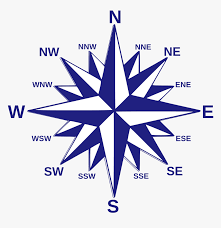

Fig. 16 point Wind Rose

% % Label Encoding- Replacing the directions with arbitraty numbers
% 
% 
% CAMSraw.WindDirection = renamecats(CAMSraw.WindDirection,{'CLM', 'N','NNE','NE','ENE','E','ESE','SE','SSE','S','SSW','SW','WSW','W','WNW','NW','NNW'},{'1','2','3','4','5','6' ...
%     ,'7','8','9','10','11','12','13','14','15','16','17'});
% CAMSraw.WindDirection = removecats(CAMSraw.WindDirection,{'blank','Wind Direction'});
% CAMSraw.WindDirection = double(CAMSraw.WindDirection);

% Removing missing values

%CAMSraw = CAMSraw(~ismissing(CAMSraw.WindDirection),:);

% Code for One hot Encoder (Only done for CAMS)- Where each category is turned into a column with 0-1 values.

% WD = string(CAMS.WindDirection);
% WD = WD';
% n = length(WD);
% 
% CLM =(sum((full(ind2vec((find(WD == 'CLM')),n)))'))';
% N =(sum((full(ind2vec((find(WD == 'N')),n)))'))';
% NNE =(sum((full(ind2vec((find(WD == 'NNE')),n)))'))';
% NE =(sum((full(ind2vec((find(WD == 'NE')),n)))'))';
% ENE =(sum((full(ind2vec((find(WD == 'ENE')),n)))'))';
% E =(sum((full(ind2vec((find(WD == 'E')),n)))'))';
% ESE =(sum((full(ind2vec((find(WD == 'ESE')),n)))'))';
% SE =(sum((full(ind2vec((find(WD == 'SE')),n)))'))';
% SSE =(sum((full(ind2vec((find(WD == 'SSE')),n)))'))';
% S =(sum((full(ind2vec((find(WD == 'S')),n)))'))';
% SSW =(sum((full(ind2vec((find(WD == 'SSW')),n)))'))';
% SW =(sum((full(ind2vec((find(WD == 'SW')),n)))'))';
% WSW =(sum((full(ind2vec((find(WD == 'WSW')),n)))'))';
% W =(sum((full(ind2vec((find(WD == 'W')),n)))'))';
% WNW =(sum((full(ind2vec((find(WD == 'WNW')),n)))'))';
% NNW =(sum((full(ind2vec((find(WD == 'NNW')),n)))'))';
% NW =(sum((full(ind2vec((find(WD == 'NW')),n)))'))';
% 
% 
% DirectionVariables = horzcat(CLM,N,NNE,NE,ENE,E,ESE,SE,SSE,S,SSW,SW,WSW,W,WNW,NNW,NW)
% DirectionVariables = array2table(DirectionVariables);
% DirectionVariables.Properties.VariableNames = ["CLM","N","NNE","NE","ENE","E","ESE","SE","SSE","S","SSW","SW","WSW","W","WNW","NNW","NW"]

## Missing Data

Finding missing entries from table

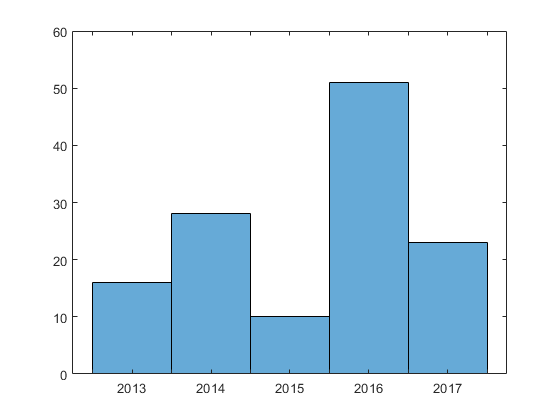

% Deleting any other column

% CAMS(:,ColumnNumber) = [];

% Removing rows with missing entries

CAMSbad = CAMSraw(ismissing(CAMSraw.PM25gm3),:);
histogram(CAMSbad.Year)

missing_values = (array2table((sum(ismissing(CAMSraw)))./ height(CAMSraw)*100));
missing_values.Properties.VariableNames = ["Year", "Month", "Day", "MaximumTemperatureC", "MinimumTemperatureC", "COppm", "SO2ppb", "NO2ppb", "O3ppb", "WindSpeedknots", "WindDirection", "RelativeHumidity", "DryBulbTemperatureC", "SolarRadiationWm2", "Rainfallmm", "SunshineHourshours","PM10gm3", "PM25gm3"];
missing_values = rows2vars(missing_values);
missing_values.Properties.VariableNames = ["Variable","Missing%"];
missing_values = sortrows(missing_values,'Missing%','descend')

missing_values = 18×2 table
           Variable            Missing%
    _______________________    ________

    {'NO2ppb'             }      17.568
    {'SO2ppb'             }      13.572
    {'COppm'              }      10.165
    {'PM10gm3'            }      9.6357
    {'PM25gm3'            }      7.5206
    {'O3ppb'              }      4.2303
    {'SolarRadiationWm2'  }      3.4665
    {'WindDirection'      }      1.8801
    {'SunshineHourshours' }     0.58754
    {'MinimumTemperatureC'}    0.058754
    {'Year'               }           0
    {'Month'              }           0
    {'Day'                }           0
    {'MaximumTemperatureC'}           0
    {'WindSpeedknots'     }           0
    {'RelativeHumidity'   }           0


## Handling Missing Data

CAMS = fillmissing(CAMSraw,"linear","EndValues","nearest");

CAMS = CAMS(CAMS.PM25gm3<1000 , :);


%plot(CAMSraw.PM25gm3, 'o')

%plot(CAMS.PM25gm3, 'linewidth',1 ,'Color','r')

CAMSdate = [CAMS(1,3),CAMS(1,2),CAMS(1,1); CAMS(end,3),CAMS(end,2),CAMS(end,1)]

CAMSdate = 2×3 table
    Day    Month    Year
    ___    _____    ____

     1      11      2012
    29       6      2017



CAMS(:,1:3)= [];


## Training and Testing Data

% Splitting the data 70-30 for training and testing


rng('default') %for reproducibility
% Cross validation (train: 70%, test: 30%)
cv = cvpartition(size(CAMS,1),'HoldOut',0.3);
idx = cv.test;
% Separate to training and test data
CAMStraining = CAMS(~idx,:);
CAMStesting  = CAMS(idx,:);
CAMStrainingmatrix = CAMStraining{:,:};
CAMStestingmatrix = CAMStesting{:,:};
CAMStraininginputmatrix = CAMStrainingmatrix(:,1:(end-1));
CAMStestinginputmatrix = CAMStestingmatrix(:,1:(end-1));
CAMStrainingPM = CAMStrainingmatrix(:,end);
CAMStestingPM = CAMStestingmatrix(:,end);

CAMSmatrix = vertcat(CAMStrainingmatrix, CAMStestingmatrix);
CAMSinputmatrix = vertcat(CAMStraininginputmatrix, CAMStestinginputmatrix);
CAMSPM = CAMSmatrix(:,end);

CAMStrainingwithoutWD = CAMStraining;
CAMStrainingwithoutWD.WindDirection = [];
CAMStrainingwithoutWDmatrix = CAMStrainingwithoutWD{:,:};
CAMStestingwithoutWD = CAMStesting;
CAMStestingwithoutWD.WindDirection = [];
CAMStestingwithoutWDmatrix = CAMStestingwithoutWD{:,:};
CAMStraininginputwithoutWDmatrix = CAMStrainingwithoutWDmatrix(:,1:(end-1));
CAMStestinginputwithoutWDmatrix = CAMStestingwithoutWDmatrix(:,1:(end-1));
CAMStrainingwithoutWDPM = CAMStrainingwithoutWDmatrix(:,end);
CAMStestingwithoutWDPM = CAMStestingwithoutWDmatrix(:,end);

CAMSwithoutWDmatrix = vertcat(CAMStrainingwithoutWDmatrix, CAMStestingwithoutWDmatrix);
CAMSwithoutWDinputmatrix = CAMSwithoutWDmatrix(:,1:(end-1));
CAMSwithoutWDPM = CAMSwithoutWDmatrix(:,end);


%This table will be used for statistics.
%size(CAMStestingwithoutWD)

## Statistical Description of Training and Testing Data


% TrainStat = [repelem(length(CAMStrainingwithoutWDmatrix),width(CAMStrainingwithoutWD)) ;mean(CAMStrainingwithoutWDmatrix)
%     ;median(CAMStrainingwithoutWDmatrix); mode(CAMStrainingwithoutWDmatrix); std(CAMStrainingwithoutWDmatrix);
%     var(CAMStrainingwithoutWDmatrix) ; skewness(CAMStrainingwithoutWDmatrix); kurtosis(CAMStrainingwithoutWDmatrix)
%     ;min(CAMStrainingwithoutWDmatrix);max(CAMStrainingwithoutWDmatrix) ];
% TrainStat = array2table(TrainStat);
% TrainStat.Properties.VariableNames = CAMStrainingwithoutWD.Properties.VariableNames;
% TrainStat.Properties.RowNames = ["N", "Mean", "Median","Mode", "Standard Deviation", "Variance", "Skewness", "Kurtosis", "Minimum" , "Maximum"]
% 
% 
% TestStat = [repelem(length(CAMStestingwithoutWDmatrix),width(CAMStestingwithoutWD)) ;mean(CAMStestingwithoutWDmatrix)
%     ;median(CAMStestingwithoutWDmatrix); mode(CAMStestingwithoutWDmatrix); std(CAMStestingwithoutWDmatrix);
%     var(CAMStestingwithoutWDmatrix) ; skewness(CAMStestingwithoutWDmatrix); kurtosis(CAMStestingwithoutWDmatrix)
%     ;min(CAMStestingwithoutWDmatrix);max(CAMStestingwithoutWDmatrix) ];
% TestStat = array2table(TestStat);
% TestStat.Properties.VariableNames = CAMStestingwithoutWD.Properties.VariableNames;
% TestStat.Properties.RowNames = ["N", "Mean", "Median","Mode", "Standard Deviation", "Variance", "Skewness", "Kurtosis", "Minimum" , "Maximum"]

## Scaling

y = $\frac{\left(y-y_{\min } \right)}{\left(y_{\max } -y_{\min } \right)}$

CAMStrainingscaledinput = rescale(CAMStraininginputmatrix,'InputMin',min(CAMSinputmatrix),'InputMax',max(CAMSinputmatrix));
CAMStestingscaledinput = rescale(CAMStestinginputmatrix,'InputMin',min(CAMSinputmatrix),'InputMax',max(CAMSinputmatrix));
CAMSscaledinput = vertcat(CAMStrainingscaledinput,CAMStestingscaledinput);
CAMSscaled = horzcat(CAMSscaledinput,CAMSPM);
CAMStrainingscaled = horzcat(CAMStrainingscaledinput, CAMStrainingPM);
CAMStestingscaled = horzcat(CAMStestingscaledinput, CAMStestingPM);

CAMStrainingwithoutWDscaledinput = rescale(CAMStraininginputwithoutWDmatrix,'InputMin',min(CAMSwithoutWDinputmatrix),'InputMax',max(CAMSwithoutWDinputmatrix));
CAMStestingwithoutWDscaledinput = rescale(CAMStestinginputwithoutWDmatrix,'InputMin',min(CAMSwithoutWDinputmatrix),'InputMax',max(CAMSwithoutWDinputmatrix));
CAMSwithoutWDscaledinput = vertcat(CAMStrainingwithoutWDscaledinput,CAMStestingwithoutWDscaledinput);
CAMSwithoutWDscaled = horzcat(CAMSwithoutWDscaledinput,CAMSwithoutWDPM);

## Correlation Matrix

% corrmatrixtotal = corrcoef(CAMSwithoutWDscaled);
% correlationmatrix = array2table(corrmatrixtotal);
% correlationmatrix.Properties.VariableNames = CAMStrainingwithoutWD.Properties.VariableNames;
% correlationmatrix.Properties.RowNames = CAMStrainingwithoutWD.Properties.VariableNames
% 
% %correlationmatrix = sortrows(correlationmatrix,'PM25gm3','descend')
% imagesc(corrmatrixtotal)
% xticks([1:1:width(CAMStrainingwithoutWD)])
% xticklabels(CAMStrainingwithoutWD.Properties.VariableNames)
% yticks([1:1:width(CAMStrainingwithoutWD)])
% yticklabels(CAMStrainingwithoutWD.Properties.VariableNames)
% xtickangle(45)
% colorbar
% title('Correlation Matrix CAMS')

## Gaussian Process 

### Exponential

% [predictedGPexp,performanceGPexp] =  gpexp(CAMStrainingscaled,CAMStestingscaled)

### Matern

% [predictedGPmatern,performanceGPmatern] =  gpmatern(CAMStrainingscaled,CAMStestingscaled)

### Rational

% [predictedGPrational,performanceGPrational] =  gprational(CAMStrainingscaled,CAMStestingscaled)

### Squared Exponential

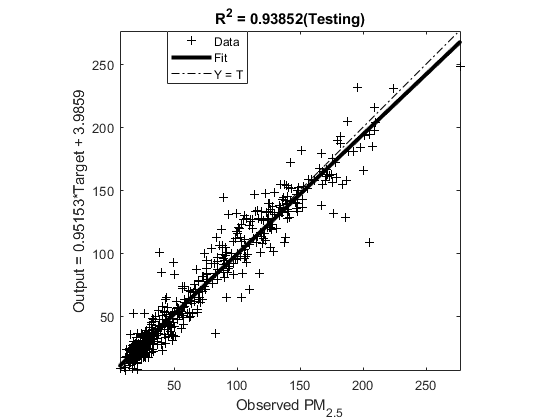

predictedGPsqrdexp =    61.0097
   47.7795
   37.6238
   47.9014
  104.9653
   89.7433
  129.8624
   65.1993
   60.2556
   47.9003


performanceGPsqrdexp = 1×4 table
       R       Rsquare     RMSE     MAE 
    _______    _______    ______    ____

    0.96877    0.93852    13.094    8.73


[predictedGPsqrdexp,performanceGPsqrdexp] =  gpsqrdexp(CAMStrainingscaled,CAMStestingscaled)

## Random Forest 

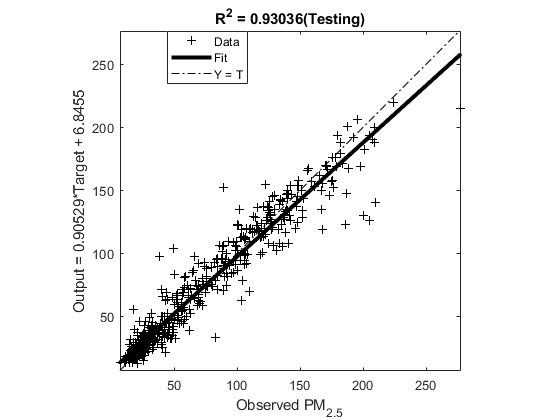

predictedRF =    54.8044
   47.2390
   38.5323
   40.8887
   98.8172
   89.4545
  117.0204
   55.2756
   60.9032
   51.2244


performanceRF = 1×4 table
       R       Rsquare    RMSE      MAE  
    _______    _______    _____    ______

    0.96455    0.93036    13.97    9.1667


[predictedRF,performanceRF] =  randomforest(CAMStrainingscaled,CAMStestingscaled)

## Tree

### Medium

% [predictedMTREE,performanceMTREE] =  MTREE(CAMStrainingscaled,CAMStestingscaled)

## Support Vector Machine

### Gaussian

#### Course

% [predictedsvmcg,performancesvmcg] =  svmcg(CAMStrainingscaled,CAMStestingscaled)

#### Medium

% [predictedsvmmg,performancesvmmg] =  svmmg(CAMStrainingscaled,CAMStestingscaled)

#### Fine

% [predictedsvmfg,performancesvmfg] =  svmfg(CAMStrainingscaled,CAMStestingscaled)

### Linear

% [predictedsvmlin,performancesvmlin] =  svmlin(CAMStrainingscaled,CAMStestingscaled)

### Quadratic

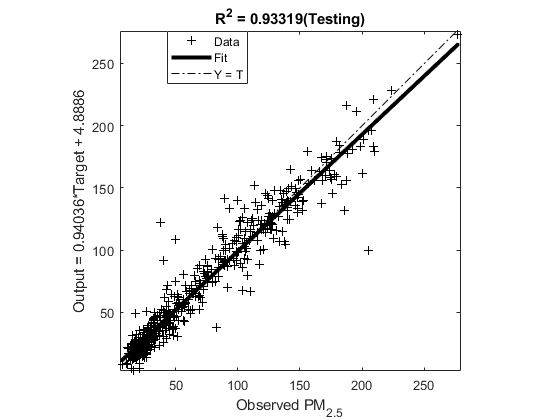

predictedsvmquad =    61.0062
   48.3806
   42.1245
   48.8924
  106.7555
   92.9997
  127.6988
   72.2010
   67.5420
   53.8494


performancesvmquad = 1×4 table
       R       Rsquare     RMSE      MAE  
    _______    _______    ______    ______

    0.96602    0.93319    13.639    8.8013


[predictedsvmquad,performancesvmquad] =  svmquad(CAMStrainingscaled,CAMStestingscaled)

## Results

% PredictedPM = horzcat(predictedGPexp, predictedGPmatern,predictedGPrational,predictedGPsqrdexp,predictedRF,predictedMTREE,predictedsvmcg,predictedsvmmg,predictedsvmfg,predictedsvmlin,predictedsvmquad);
% PredictedPM = array2table(PredictedPM);
% PredictedPM.Properties.VariableNames = ["Gaussian Process Exponential", "Gussian Process Matern","Gaussian Process Rational","Gaussian Process Squared Exponential","Random Forest","Medium TREE","Support Vector Machine Coarse Gaussian","Support Vector Machine Medium Gaussian","Support Vector Machine Fine Gaussian","Support Vector Machine Linear","Support Vector Quadratic"];
% Performance = (vertcat(performanceGPexp, performanceGPmatern,performanceGPrational,performanceGPsqrdexp,performanceRF,performanceMTREE,performancesvmcg,performancesvmmg,performancesvmfg,performancesvmlin,performancesvmquad));
% Performance.Properties.RowNames = ["Gaussian Process Exponential", "Gussian Process Matern","Gaussian Process Rational","Gaussian Process Squared Exponential","Random Forest","Medium TREE","Support Vector Machine Coarse Gaussian","Support Vector Machine Medium Gaussian","Support Vector Machine Fine Gaussian","Support Vector Machine Linear","Support Vector Quadratic"];
% 
% Performance = sortrows(Performance,'R','descend')

## Plot Predicted Values

% plot(CAMSPM,'DisplayName','Actual','LineWidth',2, 'Color', 'k');
% ylabel({'PM2.5'});
% xlabel({'Record Number'});
% title({'Actual and Predicted PM2.5 Values'});
% hold on
% plot(predictedGPmatern,'DisplayName','GPmatern','LineWidth',2, 'Color', 'k');
% plot(predictedGPexp,'DisplayName','GPexp','LineWidth',2, 'Color', 'r');
% plot(predictedGPrational,'DisplayName','GPrational','LineWidth',2, 'Color', 'g');
% plot(predictedGPsqrdexp,'DisplayName','Actual','LineWidth',2, 'Color', 'b');
% plot(predictedRF,'DisplayName','RandomForest','LineWidth',2, 'Color', 'b');
% plot(predictedMTREE,'DisplayName','DecisionTree','LineWidth',2, 'Color', 'c');
% plot(predictedsvmcg,'DisplayName','SVMcoarsegaussian','LineWidth',2, 'Color', 'y');
% plot(predictedsvmmg,'DisplayName','SVMmediumgaussian','LineWidth',2, 'Color', 'k');
% plot(predictedsvmfg,'DisplayName','SVMfinegaussian','LineWidth',2, 'Color', 'm');
% plot(predictedsvmlin,'DisplayName','SVMlinear','LineWidth',2, 'Color', 'k');
% plot(predictedsvmquad,'DisplayName','SVMquadratic','LineWidth',2, 'Color', 'y');
% plot([length(CAMStrainingscaled),length(CAMStrainingscaled)],[0,300],'DisplayName', 'Training-Testing Data Delimiter','LineWidth',1,'Color','k', 'LineStyle',"--");
% legend('Location', 'northeastoutside')
% 
% xlim([0 length(CAMSPM)])

## Sensitivity Analysis

% Mehdipour

% sensitivitym = []
% 
% for i=1:(width(CAMStesting)-1)
%     trainingdata = CAMStrainingscaled;
%     testingdata = CAMStestingscaled;
%     trainingdata(:,i) = [];
%     testingdata(:,i) = [];
%     [~,performance] = gpsqrdexp(trainingdata,testingdata);
%     sensitivitym(i,:) = performance{:,:};
% end

sensitivitym = array2table(sensitivitym);

Unrecognized function or variable 'sensitivitym'.

sensitivitym.Properties.VariableNames = [ "R" , "Rsquare" , "RMSE" , "MAE"]

% % Sihag
% sensitivitys = []
% 
% for i=1:(width(CAMStesting)-1)
%     trainingdata = CAMStrainingscaled(:,[1:i,end]);
%     testingdata = CAMStestingscaled(:,[1:i,end]);
%     [~,performance] = gpexp(trainingdata,testingdata);
%     sensitivitys(i,:) = performance{:,:};
% end
% 
% sensitivitys = array2table(sensitivitys);
% sensitivitys.Properties.VariableNames = [ "R" , "Rsquare" , "RMSE" , "MAE"]


## One way anova

% anovaGPexp = anova1(predictedGPexp,CAMSPM)
% anovaGPmatern = anova1(predictedGPmatern,CAMSPM)
% anovaGPrational = anova1(predictedGPrational,CAMSPM)
% anovaGPsqrdexp = anova1(predictedGPsqrdexp,CAMSPM)
% anovaRF = anova1(predictedRF,CAMSPM)
% anovaMTREE = anova1(predictedMTREE,CAMSPM)
% anovasvmcg = anova1(predictedsvmcg,CAMSPM)
% anovasvmmg = anova1(predictedsvmmg,CAMSPM)
% anovasvmfg = anova1(predictedsvmfg,CAMSPM)
% anovasvmlin = anova1(predictedsvmlin,CAMSPM)
% anovasvmquad = anova1(predictedsvmquad,CAMSPM)